# SNR of sweeps after applying BP FIR filter

% Loading Data
data = load("ex2data.mat");
EEG = transpose(data.eeg);
INDF = data.indf;
INDD = data.indd;

BPF = designfilt('bandpassfir', ...       % Response type
       'FilterOrder',15, ...            % Filter order
       'StopbandFrequency1',0.5, ...    % Frequency constraints
       'PassbandFrequency1',1, ...
       'PassbandFrequency2',20, ...
       'DesignMethod','ls', ...         % Design method ...
       'StopbandFrequency2',21, ...
       'SampleRate',250);               % Sample rate
EEG_BPF_FIR = filtfilt(BPF, EEG);

figure(1)
[~, ~, ~, SNR1] = SNR_func(EEG_BPF_FIR, INDF, 50, 15, 200)

SNR1 = 0.6792


figure(2)
[~, ~, ~, SNR2] = SNR_func(EEG_BPF_FIR, INDF, 100, 15, 200)

SNR2 = 1.4710


figure(3)
[~, ~, ~, SNR3] = SNR_func(EEG_BPF_FIR, INDF, 200, 15, 200)

SNR3 = 2.3989


figure(4)
[~, ~, ~, SNR4] = SNR_func(EEG_BPF_FIR, INDF,  300, 15, 200)

SNR4 = 4.1300


figure(5)
[~, ~, ~, SNR5] = SNR_func(EEG_BPF_FIR, INDF,  400, 15, 200)

SNR5 = 5.8342

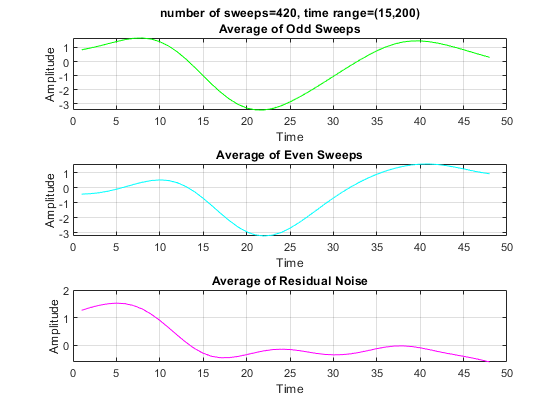

SNR6 = 5.5131


figure(6)
[~, ~, ~, SNR6] = SNR_func(EEG_BPF_FIR, INDF,  420, 15, 200)


SNRs = sprintf(['SNR1 = %G,\nSNR2 = %G,' ...
         '\nSNR3 = %G,\nSNR4 = %G,' ...
         ' \nSNR5 = %G,\nSNR6 = %G '], ...
         SNR1,SNR2,SNR3,SNR4, SNR5, SNR6)

SNRs =     'SNR1 = 0.679215,
     SNR2 = 1.47102,
     SNR3 = 2.39895,
     SNR4 = 4.13, 
     SNR5 = 5.83419,
     SNR6 = 5.51311 '
